# NSCS 344, Week 1

# Modeling simple perceptual decisions

## Perceptual decisions

For our first model, we are goint to consider a relatively "simple" type of perceptual decision. As simple as this is, and as simple as the simplest models are, decisions like these and the [models](https://en.wikipedia.org/wiki/Two-alternative_forced_choice#:~:text=The%20drift%2Ddiffusion%20model%20(DDM,of%20a%20random%20walk%20model.&text=The%20DDM%20has%20been%20shown,human%20data%20for%202AFC%20tasks.) we use to describe them are a mainstay of mathematical psychology and computational neuroscience and have been applied to everything from [memory retrieval](http://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.408.5587&rep=rep1&type=pdf) to [economic](https://www.researchgate.net/profile/Alexander_Huth/publication/47630977_The_Drift_Diffusion_Model_Can_Account_for_the_Accuracy_and_Reaction_Time_of_Value-Based_Choices_Under_High_and_Low_Time_Pressure/links/0046352f10dfd424ce000000.pdf) [decisions](https://www.pnas.org/content/108/33/13852.short). 

### Which way are these dots moving?

The particular decision we will focus on involves moving dots, an example is below.  This stimulus consists of a bunch of dots that flicker in to and out of existence. When each dot appears it moves in a "semi-random" direction. Most of the time it moves in a preferred direction (in this case to the left), but some of the time it moves in a non-preferred direction (in this case to the right).  

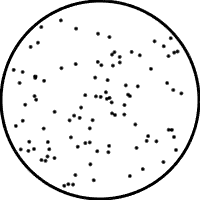

The job of the participant is to look at this stimulus and report the preferred direction that most of the dots are moving in.  For this simple stimulus, the decision is fairly easy.  But the beauty of these stimuli is that we can control the difficulty by changing the fraction of dots moving in the preferred direction $f$.  For example, by setting $f=1$ we can get a *really* easy decision ...

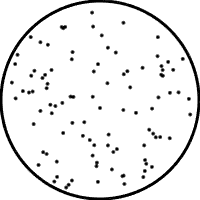

And by setting $f = 0.25$ we can get a decision that is more difficult.

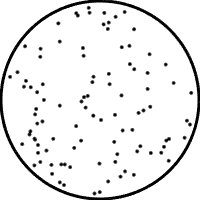

### Behavior in the moving-dots task

Unlike the moving dots above, in the simplest version of the moving-dots task, the stimulus is only presented for a short amount of time - usually less than 1 second. After the stimulus has played, subjects have to make their decision either with a button press or an eye movement.  This stimulus duration, or "viewing time," along with the fraction of dots moving in the preferred direction, gives us two variables that we can manipulate experimentally that give us some clues as to how this decision may be made.  

When these [experiments are performed](http://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.294.1540&rep=rep1&type=pdf), in this case on monkeys, we see behavior that looks like this ...

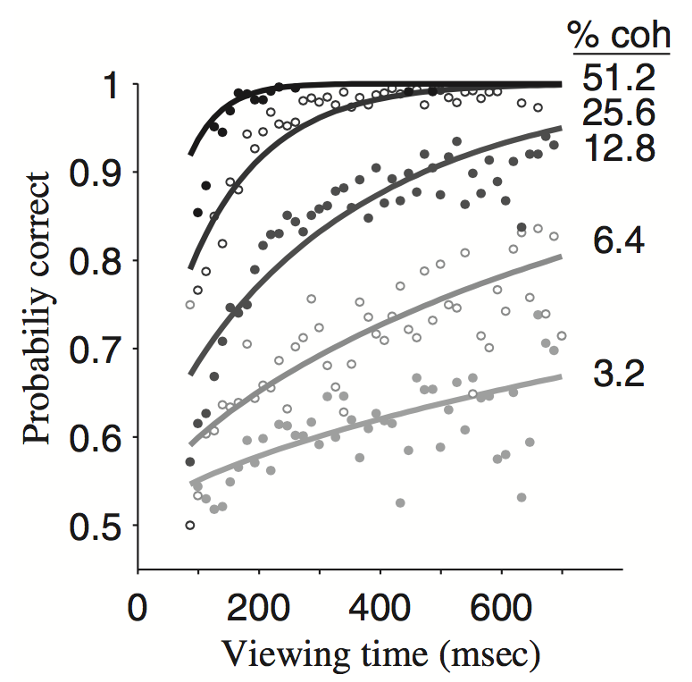 

In this plot, the data points correspond to the probability of making the correct choice as a function of viewing time and *coherence*, $COH$, which is related to the fraction moving in the preferred direction as


$$COH = 2f - 1$$


As both the viewing time and the coherence increase the monkeys are more accurate in their response. 

Note that the solid lines in this plot correspond to the behavior of a computational model of this behavior.  While the full version of this model is a bit much for our first class in computational modeling, it's actually quite easy to come up with an approximate version that shares many of the same features ...

## Our first cognitive model

Building a computational model of a cognitive process is an art form. It involves imagination and introspection as much as it involves mathematics or coding and there are choices and assumptions we have to make along the way.  

### Where to even begin?

If you consider the dots decision in detail, as trivial as this decision is, it involves a variety of different processes. To perform the task, we have to see the dots (using the output from our retina) and detect their movement with specialized circuits in the visual system. We then have to process the movement of the dots in some way to transform this pattern of movement into a decision (left or right). Then we must register our decision with a movement, a button press or saccade, which involves a signal from motor cortex to contract specific sets of muscles at specific times. 

Of course, all of the above assumes that we *understand* the task to begin with. For humans performing the task, we have to process the language in the instructions, for monkeys, they have to learn by trial and error. 

All the time in the task we were breathing, our hearts were breathing, we were fideting, and our minds were likely wandering (these tasks are usually pretty boring to perform!). Perhaps it sounds silly to consider these things, but *all* of these things have been shown to change how we process stimuli in some circumstances, why shouldn't it be the case here?

Given this complexity, the obvious question is: *Where should we even begin?* 

My advice is to always start simple, ignore as much as possible and focus on the cognitive computation that lies and the heart of the process in question. Complexity is easier (although not always easy) to add later on once you understand the simple model. And, as we shall see, even the simplest of models can lead to insights that are pretty deep ...

### A counting model of the moving-dots decision

Let's start with one of the simplest possible accounts of behavior on the dots tasks in which subjects *count* the dots.

Specifically, we will assume that they can pay attention to a subset of $D$ dots at a time. Then we will assume that they simply count how many of these dots are moving left or right over the whole movie.

We will then define

- $N_{left}$ as the number of dots going left

- $N_{right}$ as the number of dots going right

- If $N_{left} > N_{right}$ then choose left

- If $N_{left} < N_{right}$ then choose right

- If $N_{left} = N_{right}$ then choose randomly (50% left, 50% right)

And that's it for our model of the subject!  Now let's implement this model, at least for one decision, in Matlab ...

## Implementing the model in Matlab

## Setting things up

First we need to setup our script in Matlab.  It's always good to start your script with a clear command. This empties Matlab's memory, which can save you all kinds of trouble later on!  **If you run into weird bugs in later assignments, always check your code to see if you are missing the clear command at the start.**

So, after opening a new file in the Editor, we simply write

clear

Next, we need to define some variables.  In particular, we need to know how many dots we are paying attention to on each frame of the movie, $D$, as well as the number of frames people view the stimulus for, $T$, and the fraction of dots moving in the preferred direction $f$.

% number of dots participants pay attention to 
D = 100;

% viewing time in frames
T = 1;

% fraction of dots moving in the preferred direction
f = 0.6;

## Determining the direction of one dot

Now, we need to think about each dot.  Which direction is it moving in?  Specifically, is it moving in the preferred (correct) direction or the non-preferred (wrong) direction? 

Well, we know that it will be moving in the correct direction with probabiliy $f$ and in the wrong direction with probability $1-f$.  So how do we transfer this into code to set the direction of a given dot as being "correct" or "wrong"?

First let's define the direction that any dot is moving as a variable "dot_direction". This variable will be 1 if the dot is moving in the correct direction and 0 if it is moving in the wrong direction. 

Next, we need to set the value of dot_direction randomly so that it is 1 with probability $f$ and 0 with probability $f$.  To do this we are going to use a function in Matlab called binornd (short for random number from a binomial distribution). If we call this function in Matlab with this line, we will assign the dot direction to be 1 with probability $f$.

dot_direction = binornd(1, f)

dot_direction = 1

The output line underneath the code shows the value that was assigned for this particular run of the code.  But if we run it again we could get a different number.  On average, if we ran this line of code a million times, we would get 600,000 1s and 400,000 0s because we set $f = 0.6$ above.

## Determining the direction of many dots

So far so good!  We have defined some functions and we have modeled one dot. Unfortunately, we would like our model to be able to deal with more than just one dot.  In the general case, we want to have $D$ dots every frame of the movie. How do we set the direction of all of those dots?

One way to do this is to spam the copy-paste function in Matlab.  For example, if I want 10 dots I could write ...

dot_direction = binornd(1, f)

dot_direction = 0

dot_direction = binornd(1, f)

dot_direction = 1

dot_direction = binornd(1, f)

dot_direction = 1

dot_direction = binornd(1, f)

dot_direction = 1

dot_direction = binornd(1, f)

dot_direction = 0

dot_direction = binornd(1, f)

dot_direction = 1

dot_direction = binornd(1, f)

dot_direction = 1

dot_direction = binornd(1, f)

dot_direction = 1

dot_direction = binornd(1, f)

dot_direction = 1

dot_direction = binornd(1, f)

dot_direction = 1

This is OK so far as it goes, but it's not really the cleanest code you could imagine. Nor is it particularly easy to work with. If I need more dots I have to hit copy and paste a bunch more times and if I need LOTS of dots - like 1,000 or more - it's going to get pretty annoying. 

Happily, there's a way to automate this kind of repetition in Matlab (and other programming languages) using what's known as a "for loop."  The notation of these is a bit funky, but when you use for loops they look like this ...

for i = 1:10
    dot_direction = binornd(1, f)
end

dot_direction = 1

dot_direction = 1

dot_direction = 1

dot_direction = 1

dot_direction = 0

dot_direction = 0

dot_direction = 0

dot_direction = 1

dot_direction = 0

dot_direction = 1

Let's break this down.  First we start with the keyword 

You know this is an important word because Matlab automatically makes it blue. This starts the for loop and says that the following lines should be repeated. 

The 

tells Matlab when the lines that should be repeated stop. So anything written after the end isn't repeated, but anything between the for and the end is repeated. In our case, the line

dot_direction = binornd(1, f)

dot_direction = 1

is the only line that's repeated because it's the only line of code between the for and the end.

But what about the weird 

bit?

Well, this tells you how many times to repeat the for loop.  The way it does this is to create a variable $i$ that starts at 1 (first number) and increases by 1 each time (that's what the colon ":" is doing) until it reaches 10 (last number).  To see this, let's run the for loop, but get Matlab to display the value of $i$ on each run through the loop.  We can do this by simplying putting the line $i$ in there without a semi-colon so the output is displayed

for i = 1:10
    i
    dot_direction = binornd(1, f)
end

i = 1

dot_direction = 1

i = 2

dot_direction = 1

i = 3

dot_direction = 1

i = 4

dot_direction = 1

i = 5

dot_direction = 1

i = 6

dot_direction = 1

i = 7

dot_direction = 1

i = 8

dot_direction = 1

i = 9

dot_direction = 0

i = 10

dot_direction = 0

For loops are great because we can easily change how many dots we want, if we want 1000 dots I just need to change the 10 to 1000, like this ...

for i = 1:1000
    dot_direction = binornd(1, f);
end

Note that I suppressed the output by including the semicolon at the end of the line ";" (otherwise this document would get very long!).

More generally, I can make the number of items in the loop be a variable. For us, we assume people track $D$ dots every frame and that there are $T$ frames, meaning they track $D \times T$ dots overall. So ...

for i = 1:D*T
    dot_direction = binornd(1, f);
end

where the 

denotes multiplication.

## Counting the dots

Now we have to count the dots moving in the preferred and non-preferred directions. Note that this is the same as essentially the same as counting the number of dots going left or right, but it allows us to more easily determine whether the model made the correct answer or not.

To do this we need to have two counting variables, one for counting dots moving in the preferred direction and one for counting dots moving in the nonpreferred direction. Let's call these variables

At the start of our script we need to set these two variables to zero

N_correct = 0;
N_wrong = 0;

Everytime we get a dot moving in the correct direction we need to increase N_correct by 1.  We can do this by simply adding the dot_direction to N_correct

dot_direction = binornd(1, f)

dot_direction = 0

N_correct = N_correct + dot_direction

N_correct = 0

Where this line takes the *old* value of N_correct on the right hand side, adds the value of dot_direction and then updates the *new* value of N_correct on the left hand side. Note that for simplicity I've removed the for loop.

We also need to update N_wrong.  This we can do by adding 1 - dot_direction to N_wrong. 

N_wrong = N_wrong + (1 - dot_direction)

N_wrong = 1

where (1 - dotdirection) will be 0 if dot_direction is 1 and 1 if dot_direction is 0.  Putting it all together our code so far looks like this ...

clear

% number of dots participants pay attention to 
D = 100;

% viewing time in frames
T = 1;

% fraction of dots moving in the preferred direction
f = 0.6;

% initialize count variables
N_correct = 0;
N_wrong = 0;

% for loop to loop over all dots
for i = 1:D*T
    
    % randomly sample the direction of this dot
    dot_direction = binornd(1, f);
    
    % update the counts
    N_correct = N_correct + dot_direction;
    N_wrong = N_wrong + (1 - dot_direction);
    
end

% display number of dots counted in "correct" direction
N_correct

N_correct = 60

% display number of dots counted in "wrong" direction
N_wrong

N_wrong = 40

Most of the time this model will count more dots moving in the correct direction than in the incorrect direction. But it is possible, simply by chance, that we will count more dots moving in the wrong direction. The final thing to do then is compute whether we made the correct decision or not ...

## Computing the accuracy of the decision

The last thing to do is to compute the accuracy of this single decision.  Did the model make the correct decision or not on this trial? 

To compute this accuracy we need to compare the values of N_correct and N_wrong and do different things depending on which is bigger or whether they are the same. For this we are going to use the keyword

(Again you can tell that "if" is important for Matlab because the code editor automatically changes the color to blue.)

If allows us to only execute commands *if* a certain condition is met. So we can use this to only do something if N_correct is bigger than N_wrong ...

if N_correct > N_wrong
    accuracy = 1
end

accuracy = 1

You can almost read the first line here in English.  "If N_correct is greater than N_wrong" then it will execute the next lines up to the "end" statement.  Conversely, If N_correct < N_wrong or if N_correct is equal to N_wrong it won't do anything.

So that tackles the accuracy if we are definitely correct, but what if we are definitely wrong?  In that case we want to set accuracy to 0.

if N_correct < N_wrong
    accuracy = 0
end

Note there's no output here because the line accuracy = 0 is ignore. If I display the accuracy we will find it's still 1

accuracy

accuracy = 1

Finally, what if N_correct and N_wrong are tied?  Well, in that case we choose randomly so we've got a 50-50 chance of being correct.  We can get this using binornd again.

and we just need to execute this when N_correct and N_wrong are equal.  

Now, to check whether N_correct and N_wrong are equal, you might be tempted to write

But this will lead to an error in Matlab, giving you a bunch of red text in the Command Window.  The reason is that the single equals sign

is reserved for assigning quanities.  For example when we wrote

D = 100;

we weren't checking whether $D$ was 100, we were assigning the value of $D$ to be 100.

To check whether two numbers are equal we have to use *two *equals signs

So the correct way to write the if statement is like this

if N_correct == N_wrong
    accuracy = binornd(1,0.5)
end

Again, this doesn't change accuracy in this case because N_correct and N_wrong aren't equal.

## Matlab code for making one decision in the dots task

So, putting it all together, here is our complete code for modeling one decision in the dots task ...

clear

% number of dots participants pay attention to 
D = 100;

% viewing time in frames
T = 1;

% fraction of dots moving in the preferred direction
f = 0.6;

% initialize count variables
N_correct = 0;
N_wrong = 0;

% for loop to loop over all dots
for i = 1:D*T
    
    % randomly sample the direction of this dot
    dot_direction = binornd(1, f);
    
    % update the counts
    N_correct = N_correct + dot_direction;
    N_wrong = N_wrong + (1 - dot_direction);
    
end

% display number of dots counted in "correct" direction
N_correct

N_correct = 57


% display number of dots counted in "wrong" direction
N_wrong

N_wrong = 43


% compute accuracy of this choice
if N_correct > N_wrong
    accuracy = 1
end

accuracy = 1

if N_correct < N_wrong
    accuracy = 0
end
if N_correct == N_wrong
    accuracy = binornd(1,0.5)
end